# Plot S8 and S9 (other two cohort M2, M3, with C57BL6/J male mice)

## Load data

addpath(genpath('../../public_code'))

nDays = 10;
nbs = 10;

nstrain = 'male_before_timp_180511'; nNodes = 15;
nEdges = nNodes * (nNodes-1) / 2 ;
jij2_cohortm1 = zeros(nEdges, nDays);
jij2_cohortm1_nbs = zeros(nEdges, nDays, nbs);

for iday = 1:nDays
    fpday = ['sme_6h_nbs10_pseudocount_' nstrain '_iday' num2str(iday) '_full6hr.mat'];  
    load(fpday,'jij_gd_eachday','hir_gd_eachday');
    jij2_cohortm1(:, iday) = jij_gd_eachday;

    for ibs = 1:nbs
        fpday_ibs = ['sme_6h_nbs10_pseudocount_' nstrain ...
            '_iday' num2str(iday) '_ibs' num2str(ibs) '.mat'];
        load(fpday_ibs,'jij_gd_eachday','hir_gd_eachday');
        jij2_cohortm1_nbs(:, iday, ibs) = jij_gd_eachday;
    end

end



nstrain = 'male_c57_181012'; nNodes = 13;
nEdges = nNodes * (nNodes-1) / 2 ;
jij2_cohortm2 = zeros(nEdges, nDays);
jij2_cohortm2_nbs = zeros(nEdges, nDays, nbs);

for iday = 1:nDays

    fpday = ['sme_6h_nbs10_pseudocount_' nstrain '_iday' num2str(iday) '_full6hr.mat'];  
    load(fpday,'jij_gd_eachday','hir_gd_eachday');
    jij2_cohortm2(:, iday) = jij_gd_eachday;

    for ibs = 1:nbs
        fpday_ibs = ['sme_6h_nbs10_pseudocount_' nstrain ...
            '_iday' num2str(iday) '_ibs' num2str(ibs) '.mat'];
        load(fpday_ibs,'jij_gd_eachday','hir_gd_eachday');
        jij2_cohortm2_nbs(:, iday, ibs) = jij_gd_eachday;
    end

end


nstrain = 'male_c57_200701'; nNodes = 10;
nEdges = nNodes * (nNodes-1) / 2 ;
jij2_cohortm3 = zeros(nEdges, nDays);
jij2_cohortm3_nbs = zeros(nEdges, nDays, nbs);

for iday = 1:nDays
    fpday = ['sme_6h_nbs10_pseudocount_' nstrain '_iday' num2str(iday) '_full6hr.mat'];  
    load(fpday,'jij_gd_eachday','hir_gd_eachday');
    jij2_cohortm3(:, iday) = jij_gd_eachday;

    for ibs = 1:nbs
        fpday_ibs = ['sme_6h_nbs10_pseudocount_' nstrain ...
            '_iday' num2str(iday) '_ibs' num2str(ibs) '.mat'];
        load(fpday_ibs,'jij_gd_eachday','hir_gd_eachday');
        jij2_cohortm3_nbs(:, iday, ibs) = jij_gd_eachday;
    end

end


## Plot Fig S8

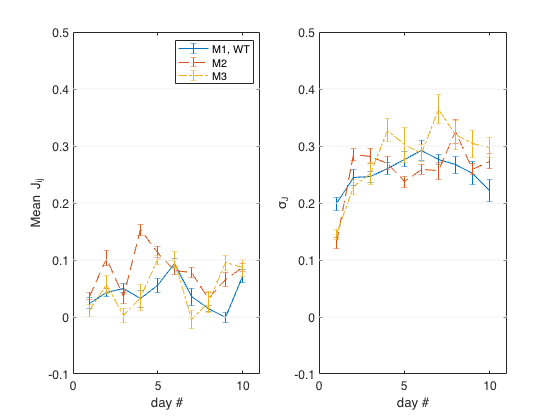

figure()
subplot(1,2,1)
errorbar(mean(mean(jij2_cohortm1_nbs),3), std(mean(jij2_cohortm1_nbs),0,3)/sqrt(2))
hold on 
errorbar(mean(mean(jij2_cohortm2_nbs),3), std(mean(jij2_cohortm2_nbs),0,3)/sqrt(2),'--')
errorbar(mean(mean(jij2_cohortm3_nbs),3), std(mean(jij2_cohortm3_nbs),0,3)/sqrt(2),'-.')
for yline = 0:0.1:0.4 
    plot([0 11],[1 1]*yline,'color',[0 0 0]+0.95)
end
hold off
ylim([-0.1 0.5])
xlabel('day #')
ylabel('Mean J_{ij}')
set(gca,'fontsize',12)
legend('M1, WT', 'M2', 'M3')

subplot(1,2,2)
% plot(std(jij2_cohortm1))
errorbar(mean(std(jij2_cohortm1_nbs),3), std(std(jij2_cohortm1_nbs),0,3)/sqrt(2))
hold on 
errorbar(mean(std(jij2_cohortm2_nbs),3), std(std(jij2_cohortm2_nbs),0,3)/sqrt(2),'--')
errorbar(mean(std(jij2_cohortm3_nbs),3), std(std(jij2_cohortm3_nbs),0,3)/sqrt(2),'-.')
for yline = 0:0.1:0.4 %-0.05:0.05:0.45
    plot([0 11],[1 1]*yline,'color',[0 0 0]+0.95)
end
hold off
% plot(std(jij2_cohortm2),'--')
% plot(std(jij2_cohortm3),'-.')
% hold off
% ylim([-0.1 0.4])
ylim([-0.1 0.5])
xlabel('day #')
ylabel('\sigma_{J}')
set(gca,'fontsize',12)

## Compute log-likelihood to plot Fig. S9 for Cohort M2

nstrain = 'male_c57_181012'; nNodes = 13;
nDays = 10;
s3 = zeros(nNodes, 21600/2, nDays);

for dayId = 0:nDays-1    
    fn = ['etho_' nstrain '_12hr_dt2s_d' num2str(dayId) '.mat'];

    load(fn,'s');
    s = s';
    s = int64(s);

    s = remove_tunnel(s);

    %%
    s = s(:,1801:1800*7);
    s3(:, :, dayId+1) = s;
end

llh2 = zeros(3, nNodes, nDays);

%
for iday = 1:nDays
    s = s3(:,:,iday);

    fpday = ['sme_6h_nbs10_pseudocount_' nstrain '_iday' num2str(iday) '_full6hr.mat'];  
    load(fpday,'jij_gd_eachday','hir_gd_eachday')

    
    for imice = 1:nNodes
    %%
        llh_null = log(0.25); 
        llh2(1, imice, iday) = llh_null;
    
        m = mean(s(imice,:) == (1:4)',2);
        llh_indep = sum (log(m) .* m);
        llh2(2, imice, iday) = llh_indep;
        
        % compute_local_energy1.
        nStates = 4;
        jijMat = recoverUpt(jij_gd_eachday, nNodes);
        hirMat = reshape(hir_gd_eachday, nNodes, nStates-1);
        hirMat = [hirMat zeros(nNodes,1)];
        
        llh = 0; nSamples = size(s,2);
        for t = 1:nSamples
            mys = s(:, t);
            localE = compute_local_energy1(mys, imice, jijMat, hirMat);
            
            localE2 = zeros(1, nStates);
            mys_temp = mys;
            for istate = 1:nStates
                mys_temp(imice) = istate;
                localE2(istate) = compute_local_energy1(mys_temp, imice, jijMat, hirMat);
            end
            lh = exp(-localE) / sum(exp(-localE2));
            llh = llh + log(lh);
        end
        llh_pw = llh / nSamples;
        llh2(3, imice, iday) = llh_pw;
    end
end


## Plot Fig. S9 for cohort M2

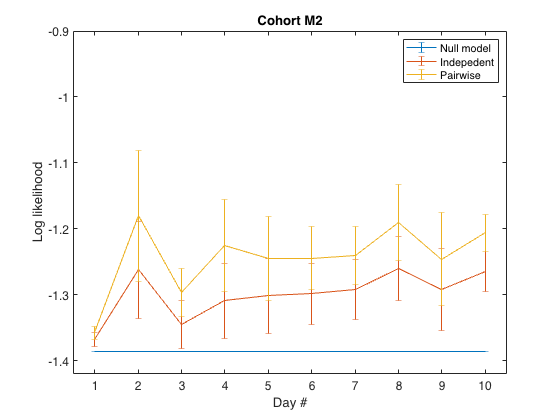

figure()

for i = 1:3
    errorbar(squeeze(mean(llh2(i,:,:),2)), ...
        squeeze(std(llh2(i,:,:),0,2)),'-')
    hold on
end
hold off

ylabel('Log likelihood')
title('Cohort M2')
set(gca,'fontsize',12)
xlabel('Day #')
legend('Null model','Indepedent','Pairwise')
xlim([0.5 10.5])
ylim([-1.42,-0.9])
yticks(-1.4:0.1:-0.9)

## As above, compute log-likelihood to plot Fig. S9 for Cohort M3

nstrain = 'male_c57_200701'; nNodes = 10;

nDays = 10;
s3 = zeros(nNodes, 21600/2, nDays);

for dayId = 0:nDays-1
    %%
    fn = ['etho_' nstrain '_12hr_dt2s_d' num2str(dayId) '.mat'];
    load(fn,'s');
    s = s';
    s = int64(s);
    s = remove_tunnel(s);
    s = s(:,1801:1800*7);
    s3(:, :, dayId+1) = s;
end

llh2 = zeros(3, nNodes, nDays);

%
for iday = 1:nDays
    s = s3(:,:,iday);

    fpday = ['sme_6h_nbs10_pseudocount_' nstrain '_iday' num2str(iday) '_full6hr.mat'];  
    load(fpday,'jij_gd_eachday','hir_gd_eachday')

    
    for imice = 1:nNodes
    %%
        llh_null = log(0.25); 
        llh2(1, imice, iday) = llh_null;
    
        m = mean(s(imice,:) == (1:4)',2);
        llh_indep = sum (log(m) .* m);
        llh2(2, imice, iday) = llh_indep;
        
        % compute_local_energy1.
        nStates = 4;
        jijMat = recoverUpt(jij_gd_eachday, nNodes);
        hirMat = reshape(hir_gd_eachday, nNodes, nStates-1);
        hirMat = [hirMat zeros(nNodes,1)];
        
        llh = 0; nSamples = size(s,2);
        for t = 1:nSamples
            mys = s(:, t);
            localE = compute_local_energy1(mys, imice, jijMat, hirMat);
            
            localE2 = zeros(1, nStates);
            mys_temp = mys;
            for istate = 1:nStates
                mys_temp(imice) = istate;
                localE2(istate) = compute_local_energy1(mys_temp, imice, jijMat, hirMat);
            end
            lh = exp(-localE) / sum(exp(-localE2));
            llh = llh + log(lh);
        end
        llh_pw = llh / nSamples;
        llh2(3, imice, iday) = llh_pw;
    end
end


## Plot Fig. S9 for cohort M3

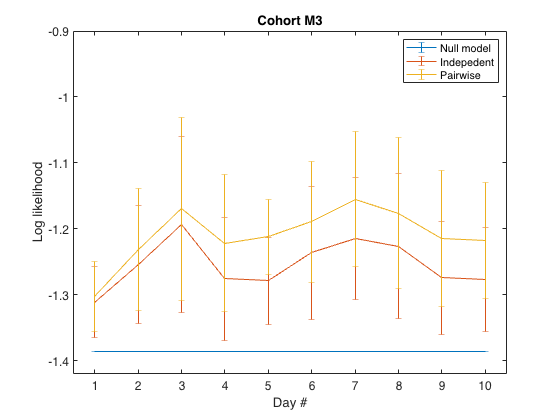

figure()
for i = 1:3
    errorbar(squeeze(mean(llh2(i,:,:),2)), ...
        squeeze(std(llh2(i,:,:),0,2)),'-')
    hold on
end
hold off

ylabel('Log likelihood')
title('Cohort M3')
set(gca,'fontsize',12)
xlabel('Day #')
legend('Null model','Indepedent','Pairwise')
xlim([0.5 10.5])
ylim([-1.42,-0.9])
yticks(-1.4:0.1:-0.9)